# Solving the 1st Order Linear ODEs using Modified Euler Method

*MohammadSina GhanbariPakdehi, Chemical and Petroleum Engineering Department, Fall 2021*

The Modified Euler method, also known as Heun's method, is a more accurate numerical technique used to approximate the solution of ordinary differential equations (ODEs) compared to the basic Euler method. This document provides an explanation and implementation of the Modified Euler method for solving ODEs using MATLAB. The provided code takes an equation, initial values, and a range of x values as input, and then computes and plots the approximate solution using the Modified Euler method.

Each 1st order ODE can be showed as a function of dependent variables. for example:


$$\frac{\mathrm{dy}}{\mathrm{dx}}=-2x^3 +12x^2 -20x+8\ldotp 5=f\left(x,y\right)$$


The iterative method is showed as follows:


$$y_{i+1} =y_i +\frac{h}{2}\left({y_i }^{\prime } +{y_{i+1} }^{\prime } \right)=y_i +\frac{h}{2}\;\left(f\left(x_i ,y_i \right)+f\left(x_{i+1} ,y_{i+1} \right)\right)$$


### Part1: Input data

clear, clc
syms x
syms y
f = input('Enter the equation of f(x, y): ');
% if your function doesn't have 'y' or 'x' variable, insert '0*y' or '*x' in the end of function equation

X = input('Enter the range of xi as a vector: ');

% Initialize the y values vector with ones and input initial value y0
Y = ones(1, length(X));
X(1, 1) = input('Enter the value of x0: ');
Y(1, 1) = input('Enter the value of y0: ');

### Part2: ODE Calculation

for i = 2:length(X)
    h = X(i) - X(i - 1); % Step size
    k1 = h * double(subs(f, [x, y], [X(i - 1), Y(1, i - 1)]));
    k2 = h * double(subs(f, [x, y], [X(i), Y(1, i - 1) + k1]));
    Y(1, i) = Y(1, i - 1) + (k1 + k2) / 2;
end
Xi = X';
Yi = Y';
i = (0:(length(X)-1))';

### Part3: Results & Visualization

result = table(i,Xi,Yi);
disp('The results of calculation are:'), disp(result)

The results of calculation are:
    i    Xi      Yi 
    _    ___    ____

    0      0       1
    1    0.5    2.75
    2      1       4
    3    1.5    4.75
    4      2       5



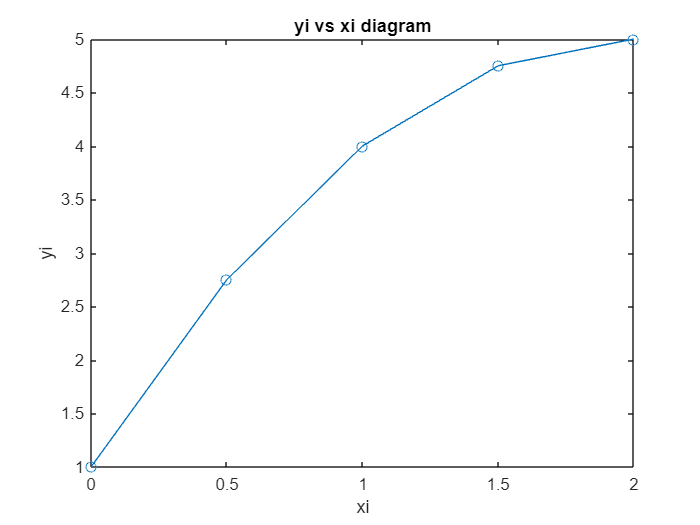

plot(X, Y, '-o')
xlabel('xi')
ylabel('yi')
title('yi vs xi diagram')